% % Load the dataset
% load('dataset2.mat');
% 
% % Initialize variables
% % T = 0.1; % Sampling period
% num_timesteps = length(t);
% x_est = zeros(num_timesteps, 3); % [x, y, theta] estimates
% P_est = zeros(3, 3, num_timesteps); % Covariance matrix
% 
% % Initial condition
% % x_est(1, :) = [x_true(1), y_true(1), th_true(1)]; % True initial position
% x_est(1, :) = [200000, 200000, 3.1415];
% P_est(:, :, 1) = diag([1, 1, 0.1]); % Initial covariance
% Q_k = diag([v_var, om_var]);
% 
% % Define r_max values to test
% r_max_values = [5, 3, 1];
% 
% for i = 1:length(r_max_values)
%     r_max = r_max_values(i);
%     
%     % EKF loop for each timestep
%     for k = 2:num_timesteps
%         % Previous state
%         x_prev = x_est(k-1, :)';
%         v_k = v(k);
%         omega_k = om(k);
%         T = t(k)-t(k-1);
%         
%         % Prediction step
%         F_km1 = [1, 0, -v_k * sin(x_prev(3)) * T;
%                0, 1, v_k * cos(x_prev(3)) * T;
%                0, 0, 1];
%         
%         B_km1 = [T * cos(x_prev(3)), 0;
%                T * sin(x_prev(3)), 0;
%                0, T];
%         
%         % State prediction
%         x_pred = x_prev + T * [v_k * cos(x_prev(3));
%                                v_k * sin(x_prev(3));
%                                omega_k];
%         
%         % Covariance prediction
%         P_pred = F_km1 * P_est(:, :, k-1) * F_km1' + B_km1 * Q_k * B_km1';
%         
%         % Measurement update
%         % Find visible landmarks
%         visible_landmarks = find((r(k, :) ~= 0) & (r(k, :) <= r_max));
%         num_landmarks = length(visible_landmarks);
%         
%         % Initialize stacked Jacobian G_k and measurement noise matrix N_k
%         G_k = [];
%         N_k = [];
%         z_k = [];  % Stacked measurement vector
%         z_pred = [];  % Stacked predicted measurement vector
%         
%         for landmark = visible_landmarks
%             % Landmark position
%             lx = l(landmark, 1);
%             ly = l(landmark, 2);
%             
%             % Calculate predicted measurement for the landmark using the new formula for a, b, and c
%             a = lx - x_pred(1) - d * cos(x_pred(3));
%             b1 = ly - x_pred(2) - d * sin(x_pred(3)); % call it b1 cuz b is already a variable
%             c = sqrt(a^2 + b1^2);
%             
%             % Predicted range and bearing
%             r_pred = c;
%             phi_pred = atan2(b1, a) - x_pred(3);
%             
%             % Measurement model for this landmark
%             huh1 = d*(a*sin(x_pred(3))-b1*cos(x_pred(3)))/c;
%             huh2 = -d*(a*cos(x_pred(3))+b1*sin(x_pred(3)))/c^2 - 1;
%             G_k_l = [-a/c, -b1/c, huh1;
%                       b1/c^2, -a/c^2, huh2];
%             
%             % Stack G_k_l to form G_k for all landmarks
%             G_k = [G_k; G_k_l];
%             
%             % Stack measurement noise matrix
%             N_k_l = diag([r_var, b_var]);
%             N_k = blkdiag(N_k, N_k_l);
%             
%             % Stack measurements and predictions
%             z_k = [z_k; r(k, landmark); b(k, landmark)];
%             z_pred = [z_pred; r_pred; phi_pred];
%         end
%         
%         % Compute Kalman gain for stacked measurements only if there are visible landmarks
%         if ~isempty(visible_landmarks)
%             % Display the size of G_k for debugging            
%             S_k = G_k * P_pred * G_k' + N_k;
%             K_k = P_pred * G_k' / S_k;
%             
%             % Update state and covariance in a single step
%             innovation = z_k - z_pred;
%             % Define the bounds in radians
%             lower_bound = -2 * pi / 3;
%             upper_bound = 2 * pi / 3;
%             
%             % Loop through every 2nd element in the innovation vector
%             for i2 = 2:2:length(innovation)
%                 % Normalize the angle to be within -pi and pi
%                 innovation(i2) = mod(innovation(i2) + pi, 2 * pi) - pi;
%                 
%                 % Further wrap it to be within the -2pi/3 to 2pi/3 range
%                 if innovation(i2) > upper_bound
%                     innovation(i2) = innovation(i2) - 2 * pi;
%                 elseif innovation(i2) < lower_bound
%                     innovation(i2) = innovation(i2) + 2 * pi;
%                 end
%             end
%             x_pred = x_pred + K_k * innovation;
%             x_pred(3) = mod(x_pred(3) + pi, 2 * pi) - pi;
%             % Further wrap it to be within the -2pi/3 to 2pi/3 range
%             if x_pred(3) > upper_bound
%                 x_pred(3) = x_pred(3) - 2 * pi;
%             elseif x_pred(3) < lower_bound
%                 x_pred(3) = x_pred(3) + 2 * pi;
%             end
%             P_pred = (eye(3) - K_k * G_k) * P_pred;
%         end
%         
%         % Store the results (whether updated or not)
%         x_est(k, :) = x_pred';
%         P_est(:, :, k) = P_pred;
%     end
%     
%     % Plot results
%     figure;
%     for j = 1:3
%         subplot(3, 1, j);
%         if j == 1
%             % Plot x error and uncertainty
%             plot(t, x_est(:, 1) - x_true, 'b', 'LineWidth', 1.5);
%             hold on;
%             plot(t, 3 * sqrt(squeeze(P_est(1, 1, :))), 'r--');
%             plot(t, -3 * sqrt(squeeze(P_est(1, 1, :))), 'r--');
%             ylim([-10, 10]);
%             ylabel('Error in x [m]');
%         elseif j == 2
%             % Plot y error and uncertainty
%             plot(t, x_est(:, 2) - y_true, 'b', 'LineWidth', 1.5);
%             hold on;
%             plot(t, 3 * sqrt(squeeze(P_est(2, 2, :))), 'r--');
%             plot(t, -3 * sqrt(squeeze(P_est(2, 2, :))), 'r--');
%             ylim([-10, 10]);
%             ylabel('Error in y [m]');
%         else
%             % Plot theta error and uncertainty
%             error_th = x_est(:, 3) - th_true;
%             for i2 = 1:length(error_th)
%                 % Normalize the angle to be within -pi and pi
%                 error_th(i2) = mod(error_th(i2) + pi, 2 * pi) - pi;
%                 
%                 % Further wrap it to be within the -2pi/3 to 2pi/3 range
%                 if error_th(i2) > upper_bound
%                     error_th(i2) = error_th(i2) - 2 * pi;
%                 elseif error_th(i2) < lower_bound
%                     error_th(i2) = error_th(i2) + 2 * pi;
%                 end
%             end
%             plot(t, error_th, 'b', 'LineWidth', 1.5);
%             hold on;
%             plot(t, 3 * sqrt(squeeze(P_est(3, 3, :))), 'r--');
%             plot(t, -3 * sqrt(squeeze(P_est(3, 3, :))), 'r--');
%             ylim([min(error_th), max(error_th)]);
%             ylabel('Error in \theta [rad]');
%         end
%         xlabel('Time [s]');
%         legend('Error', '3\sigma Envelope');
%     end
%     sgtitle(['EKF Results for r_{max} = ', num2str(r_max)]);
% end

% % 4c
% % Load the dataset
% load('dataset2.mat');
% 
% % Initialize variables
% % T = 0.1; % Sampling period
% num_timesteps = length(t);
% x_est = zeros(num_timesteps, 3); % [x, y, theta] estimates
% P_est = zeros(3, 3, num_timesteps); % Covariance matrix
% 
% % Initial condition
% x_est(1, :) = [x_true(1), y_true(1), th_true(1)]; % True initial position
% % x_est(1, :) = [200000, 200000, 3.1415];
% P_est(:, :, 1) = diag([1, 1, 0.1]); % Initial covariance
% Q_k = diag([v_var, om_var]);
% 
% % Define r_max values to test
% r_max_values = [5, 3, 1];
% 
% for i = 1:length(r_max_values)
%     r_max = r_max_values(i);
%     
%     % EKF loop for each timestep
%     for k = 2:num_timesteps
%         % Previous state using true values for Jacobians
%         x_true_prev = [x_true(k-1), y_true(k-1), th_true(k-1)]';
%         v_k = v(k);
%         omega_k = om(k);
%         T = t(k) - t(k-1);     
% 
%         % Prediction step (using x_true for Jacobian evaluation)
%         F_km1 = [1, 0, -v_k * sin(th_true(k-1)) * T;
%                  0, 1, v_k * cos(th_true(k-1)) * T;
%                  0, 0, 1];
%         
%         B_km1 = [T * cos(th_true(k-1)), 0;
%                  T * sin(th_true(k-1)), 0;
%                  0, T];
%         
%         % State prediction using the estimated state
%         x_pred = x_est(k-1, :)' + T * [v_k * cos(x_est(k-1, 3));
%                                        v_k * sin(x_est(k-1, 3));
%                                        omega_k];
%         
%         % Covariance prediction
%         P_pred = F_km1 * P_est(:, :, k-1) * F_km1' + B_km1 * Q_k * B_km1';
%         
%         % Measurement update
%         % Find visible landmarks
%         visible_landmarks = find((r(k, :) ~= 0) & (r(k, :) <= r_max));
%         num_landmarks = length(visible_landmarks);
%         
%         % Initialize stacked Jacobian G_k and measurement noise matrix N_k
%         G_k = [];
%         N_k = [];
%         z_k = [];  % Stacked measurement vector
%         z_pred = [];  % Stacked predicted measurement vector
%         
%         for landmark = visible_landmarks
%             % Landmark position
%             lx = l(landmark, 1);
%             ly = l(landmark, 2);
%             
%             % Calculate predicted measurement using true state for Jacobian
%             a = lx - x_true(k) - d * cos(th_true(k));
%             b1 = ly - y_true(k) - d * sin(th_true(k));
%             c = sqrt(a^2 + b1^2);
%             
%             % Predicted range and bearing using estimated state
%             r_pred = sqrt((lx - x_pred(1) - d * cos(x_pred(3)))^2 + (ly - x_pred(2) - d * sin(x_pred(3)))^2);
%             phi_pred = atan2(ly - x_pred(2) - d * sin(x_pred(3)), lx - x_pred(1) - d * cos(x_pred(3))) - x_pred(3);
%             
%             % Measurement model Jacobian G_k_l evaluated at true state
%             G_k_l = [-a / c, -b1 / c, d * (a * sin(th_true(k)) - b1 * cos(th_true(k))) / c;
%                      b1 / c^2, -a / c^2, -d * (a * cos(th_true(k)) + b1 * sin(th_true(k))) / c^2 - 1];
%             
%             % Stack G_k_l to form G_k for all landmarks
%             G_k = [G_k; G_k_l];
%             
%             % Stack measurement noise matrix
%             N_k_l = diag([r_var, b_var]);
%             N_k = blkdiag(N_k, N_k_l);
%             
%             % Stack measurements and predictions
%             z_k = [z_k; r(k, landmark); b(k, landmark)];
%             z_pred = [z_pred; r_pred; phi_pred];
%         end
%         
%         % Compute Kalman gain for stacked measurements only if there are visible landmarks
%         if ~isempty(visible_landmarks)
%             % Display the size of G_k for debugging            
%             S_k = G_k * P_pred * G_k' + N_k;
%             K_k = P_pred * G_k' / S_k;
%             
%             % Update state and covariance in a single step
%             innovation = z_k - z_pred;
%             % Define the bounds in radians
%             lower_bound = -2 * pi / 3;
%             upper_bound = 2 * pi / 3;
%             
%             % Loop through every 2nd element in the innovation vector
%             for i2 = 2:2:length(innovation)
%                 % Normalize the angle to be within -pi and pi
%                 innovation(i2) = mod(innovation(i2) + pi, 2 * pi) - pi;
%                 
%                 % Further wrap it to be within the -2pi/3 to 2pi/3 range
%                 if innovation(i2) > upper_bound
%                     innovation(i2) = innovation(i2) - 2 * pi;
%                 elseif innovation(i2) < lower_bound
%                     innovation(i2) = innovation(i2) + 2 * pi;
%                 end
%             end
%             x_pred = x_pred + K_k * innovation;
%             x_pred(3) = mod(x_pred(3) + pi, 2 * pi) - pi;
%             % Further wrap it to be within the -2pi/3 to 2pi/3 range
%             if x_pred(3) > upper_bound
%                 x_pred(3) = x_pred(3) - 2 * pi;
%             elseif x_pred(3) < lower_bound
%                 x_pred(3) = x_pred(3) + 2 * pi;
%             end
%             P_pred = (eye(3) - K_k * G_k) * P_pred;
%         end
%         
%         % Store the results (whether updated or not)
%         x_est(k, :) = x_pred';
%         P_est(:, :, k) = P_pred;
%     end
%     
%     % Plot results
%     figure;
%     for j = 1:3
%         subplot(3, 1, j);
%         if j == 1
%             % Plot x error and uncertainty
%             plot(t, x_est(:, 1) - x_true, 'b', 'LineWidth', 1.5);
%             hold on;
%             plot(t, 3 * sqrt(squeeze(P_est(1, 1, :))), 'r--');
%             plot(t, -3 * sqrt(squeeze(P_est(1, 1, :))), 'r--');
%             ylim([-0.5, 0.5]);
%             ylabel('Error in x [m]');
%         elseif j == 2
%             % Plot y error and uncertainty
%             plot(t, x_est(:, 2) - y_true, 'b', 'LineWidth', 1.5);
%             hold on;
%             plot(t, 3 * sqrt(squeeze(P_est(2, 2, :))), 'r--');
%             plot(t, -3 * sqrt(squeeze(P_est(2, 2, :))), 'r--');
%             ylim([-0.3, 0.3]);
%             ylabel('Error in y [m]');
%         else
%             % Plot theta error and uncertainty
%             error_th = x_est(:, 3) - th_true;
%             for i2 = 1:length(error_th)
%                 % Normalize the angle to be within -pi and pi
%                 error_th(i2) = mod(error_th(i2) + pi, 2 * pi) - pi;
%                 
%                 % Further wrap it to be within the -2pi/3 to 2pi/3 range
%                 if error_th(i2) > upper_bound
%                     error_th(i2) = error_th(i2) - 2 * pi;
%                 elseif error_th(i2) < lower_bound
%                     error_th(i2) = error_th(i2) + 2 * pi;
%                 end
%             end
%             plot(t, error_th, 'b', 'LineWidth', 1.5);
%             hold on;
%             plot(t, 3 * sqrt(squeeze(P_est(3, 3, :))), 'r--');
%             plot(t, -3 * sqrt(squeeze(P_est(3, 3, :))), 'r--');
%             ylim([-0.3, 0.3]);
%             ylabel('Error in \theta [rad]');
%         end
%         xlabel('Time [s]');
%         legend('Error', '3\sigma Envelope');
%     end
%     sgtitle(['EKF Results for r_{max} = ', num2str(r_max)]);
% end

% % 5
% % Load the dataset
% load('dataset2.mat');
% 
% % Initialize variables
% num_timesteps = length(t);
% x_est = zeros(num_timesteps, 3); % [x, y, theta] estimates
% P_est = zeros(3, 3, num_timesteps); % Covariance matrix
% 
% % Initial condition
% x_est(1, :) = [x_true(1), y_true(1), th_true(1)];
% P_est(:, :, 1) = diag([1, 1, 0.1]); % Initial covariance
% Q_k = diag([v_var, om_var]);
% 
% % Set r_max and initialize the video writer
% r_max = 1;
% videoEKF = VideoWriter('EKF_animation.avi');
% videoEKF.FrameRate = 5;
% open(videoEKF);
% 
% figure;
% hold on;
% 
% % Plot static landmarks
% plot(l(:, 1), l(:, 2), 'k.', 'MarkerSize', 10); % Landmarks in black
% % EKF loop
% for k = 2:num_timesteps
%     if mod(k, 500) == 0
%         disp(k);
%     end
%     % Time step
%     T = t(k) - t(k-1);
% 
%     % Previous state
%     x_prev = x_est(k-1, :)';
%     v_k = v(k);
%     omega_k = om(k);
%     
%     % Prediction step
%     F_km1 = [1, 0, -v_k * sin(x_prev(3)) * T;
%              0, 1, v_k * cos(x_prev(3)) * T;
%              0, 0, 1];
%     B_km1 = [T * cos(x_prev(3)), 0;
%              T * sin(x_prev(3)), 0;
%              0, T];
%     
%     % State prediction
%     x_pred = x_prev + T * [v_k * cos(x_prev(3));
%                            v_k * sin(x_prev(3));
%                            omega_k];
%     P_pred = F_km1 * P_est(:, :, k-1) * F_km1' + B_km1 * Q_k * B_km1';
% 
%     % Measurement update with visible landmarks
%     visible_landmarks = find((r(k, :) ~= 0) & (r(k, :) <= r_max));
%     G_k = [];
%     N_k = [];
%     z_k = [];
%     z_pred = [];
%     
%     for landmark = visible_landmarks
%         lx = l(landmark, 1);
%         ly = l(landmark, 2);
%         
%         % Measurement model
%         a = lx - x_pred(1);
%         b1 = ly - x_pred(2);
%         c = sqrt(a^2 + b1^2);
%         
%         r_pred = c;
%         phi_pred = atan2(b1, a) - x_pred(3);
%         
%         % Measurement Jacobian
%         G_k_l = [-a / c, -b1 / c, 0;
%                   b1 / c^2, -a / c^2, -1];
%         
%         % Stack G_k and measurement noise
%         G_k = [G_k; G_k_l];
%         N_k_l = diag([r_var, b_var]);
%         N_k = blkdiag(N_k, N_k_l);
%         
%         % Stack measurements and predictions
%         z_k = [z_k; r(k, landmark); b(k, landmark)];
%         z_pred = [z_pred; r_pred; phi_pred];
%     end
% 
%     if ~isempty(visible_landmarks)
%         S_k = G_k * P_pred * G_k' + N_k;
%         K_k = P_pred * G_k' / S_k;
%         innovation = z_k - z_pred;
%         
%         % Angle wrapping for the bearing
%         for i2 = 2:2:length(innovation)
%             innovation(i2) = mod(innovation(i2) + pi, 2 * pi) - pi;
%         end
%         
%         % State and covariance update
%         x_pred = x_pred + K_k * innovation;
%         P_pred = (eye(3) - K_k * G_k) * P_pred;
%     end
% 
%     % Store results
%     x_est(k, :) = x_pred';
%     P_est(:, :, k) = P_pred;
%     
%     % Clear current frame
%     clf;
%     hold on;
% 
%     % Plot static landmarks
%     plot(l(:, 1), l(:, 2), 'k.', 'MarkerSize', 10); % Landmarks in black
% 
%     % Plot true robot position
%     plot(x_true(1:k), y_true(1:k), 'b'); % Trajectory in blue
%     plot(x_true(k), y_true(k), 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'blue'); % Current position in blue
% 
%     % Plot estimated robot position
%     plot(x_est(1:k, 1), x_est(1:k, 2), 'r'); % Estimated trajectory in red
%     plot(x_est(k, 1), x_est(k, 2), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'red'); % Current estimate in red
% 
%     % Plot 3-sigma covariance ellipse
%     [eig_vec, eig_val] = eig(P_pred(1:2, 1:2));
%     theta = linspace(0, 2 * pi, 100);
%     ellipse_x = 3 * sqrt(eig_val(1, 1)) * cos(theta);
%     ellipse_y = 3 * sqrt(eig_val(2, 2)) * sin(theta);
%     ellipse_points = [ellipse_x; ellipse_y]' * eig_vec';
%     plot(ellipse_points(:, 1) + x_est(k, 1), ellipse_points(:, 2) + x_est(k, 2), 'r--'); % Covariance ellipse in red
%     
%     % Set plot limits and labels
%     axis equal;
%     xlim([-10, 10]);
%     ylim([-10, 10]);
%     xlabel('x [m]');
%     ylabel('y [m]');
%     title(['EKF Animation at timestep ', num2str(k), ', r_{max} = ', num2str(r_max)]);
% 
%     % Capture frame for video
%     frame = getframe(gcf);
%     writeVideo(videoEKF, frame);
% end
% Close video writer
% close(videoEKF);

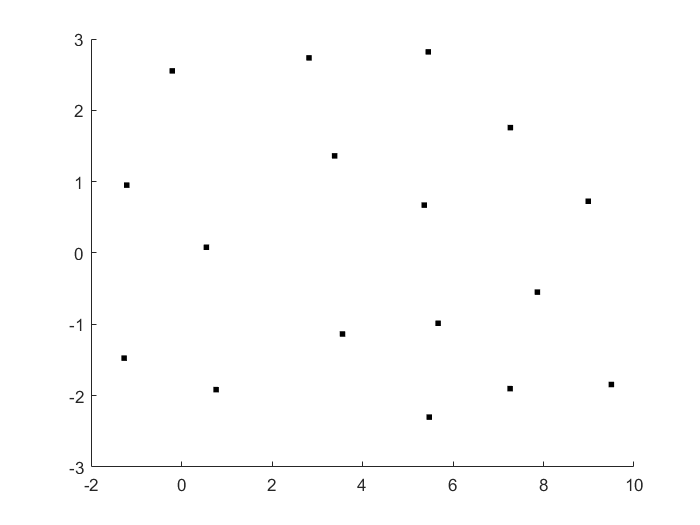

% Load the dataset
load('dataset2.mat');

% Initialize variables
num_timesteps = length(t);
x_est = zeros(num_timesteps, 3); % [x, y, theta] estimates
P_est = zeros(3, 3, num_timesteps); % Covariance matrix

% Initial condition
x_est(1, :) = [200000, 200000, 3.1415];
P_est(:, :, 1) = diag([1, 1, 0.1]); % Initial covariance
Q_k = diag([v_var, om_var]);

% Set r_max and initialize the video writer
r_max = 1;
videoEKF = VideoWriter('EKF_animation.avi');
videoEKF.FrameRate = 10;
open(videoEKF);

figure;
hold on;

% Plot static landmarks
plot(l(:, 1), l(:, 2), 'k.', 'MarkerSize', 10); % Landmarks in black

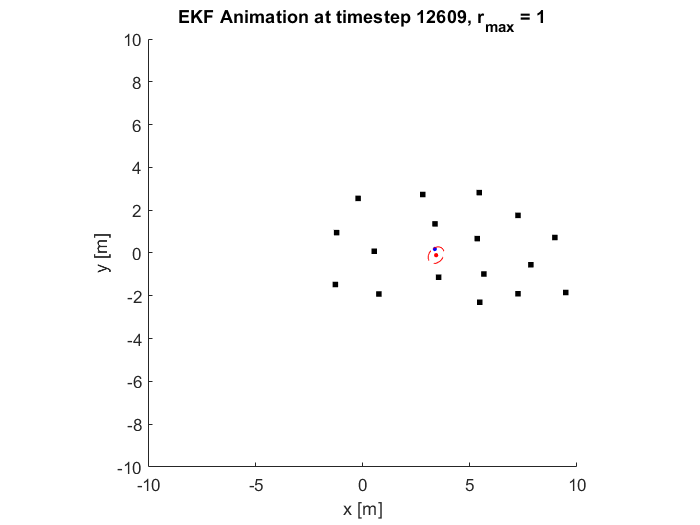


% EKF loop
for k = 2:num_timesteps
    % Time step
    T = t(k) - t(k-1);

    % Previous state
    x_prev = x_est(k-1, :)';
    v_k = v(k);
    omega_k = om(k);
    
    % Prediction step
    F_km1 = [1, 0, -v_k * sin(x_prev(3)) * T;
             0, 1, v_k * cos(x_prev(3)) * T;
             0, 0, 1];
    B_km1 = [T * cos(x_prev(3)), 0;
             T * sin(x_prev(3)), 0;
             0, T];
    
    % State prediction
    x_pred = x_prev + T * [v_k * cos(x_prev(3));
                           v_k * sin(x_prev(3));
                           omega_k];
    P_pred = F_km1 * P_est(:, :, k-1) * F_km1' + B_km1 * Q_k * B_km1';

    % Measurement update with visible landmarks
    visible_landmarks = find((r(k, :) ~= 0) & (r(k, :) <= r_max));
    G_k = [];
    N_k = [];
    z_k = [];
    z_pred = [];
    
    for landmark = visible_landmarks
        lx = l(landmark, 1);
        ly = l(landmark, 2);
        
        % Measurement model
        a = lx - x_pred(1);
        b1 = ly - x_pred(2);
        c = sqrt(a^2 + b1^2);
        
        r_pred = c;
        phi_pred = atan2(b1, a) - x_pred(3);
        
        % Measurement Jacobian
        G_k_l = [-a / c, -b1 / c, 0;
                  b1 / c^2, -a / c^2, -1];
        
        % Stack G_k and measurement noise
        G_k = [G_k; G_k_l];
        N_k_l = diag([r_var, b_var]);
        N_k = blkdiag(N_k, N_k_l);
        
        % Stack measurements and predictions
        z_k = [z_k; r(k, landmark); b(k, landmark)];
        z_pred = [z_pred; r_pred; phi_pred];
    end

    if ~isempty(visible_landmarks)
        S_k = G_k * P_pred * G_k' + N_k;
        K_k = P_pred * G_k' / S_k;
        innovation = z_k - z_pred;
        
        % Angle wrapping for the bearing
        for i2 = 2:2:length(innovation)
            innovation(i2) = mod(innovation(i2) + pi, 2 * pi) - pi;
        end
        
        % State and covariance update
        x_pred = x_pred + K_k * innovation;
        P_pred = (eye(3) - K_k * G_k) * P_pred;
    end

    % Store results
    x_est(k, :) = x_pred';
    P_est(:, :, k) = P_pred;
    
    % Clear current frame
    clf;
    hold on;

    % Plot static landmarks
    plot(l(:, 1), l(:, 2), 'k.', 'MarkerSize', 10); % Landmarks in black

    % Plot current true robot position (smaller blue dot)
    plot(x_true(k), y_true(k), 'bo', 'MarkerSize', 2, 'MarkerFaceColor', 'blue'); % Current position in blue

    % Plot current estimated robot position (smaller red dot)
    plot(x_est(k, 1), x_est(k, 2), 'ro', 'MarkerSize', 2, 'MarkerFaceColor', 'red'); % Current estimate in red

    % Plot 3-sigma covariance ellipse
    [eig_vec, eig_val] = eig(P_pred(1:2, 1:2));
    theta = linspace(0, 2 * pi, 100);
    ellipse_x = 3 * sqrt(eig_val(1, 1)) * cos(theta);
    ellipse_y = 3 * sqrt(eig_val(2, 2)) * sin(theta);
    ellipse_points = [ellipse_x; ellipse_y]' * eig_vec';
    plot(ellipse_points(:, 1) + x_est(k, 1), ellipse_points(:, 2) + x_est(k, 2), 'r'); % Covariance ellipse in red
    
    % Set plot limits and labels
    axis equal;
%     xlim([-10, 10]);
%     ylim([-10, 10]);
    xlabel('x [m]');
    ylabel('y [m]');
    title(['EKF Animation at timestep ', num2str(k), ', r_{max} = ', num2str(r_max)]);

    % Capture frame for video
    frame = getframe(gcf);
    writeVideo(videoEKF, frame);
end


% Close video writer
close(videoEKF);
